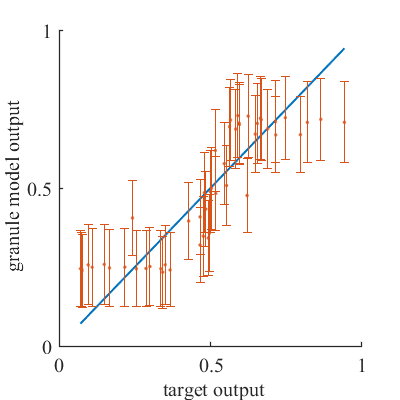

close all
clear all

original_data = load('check_data.txt');
Y = load('Y_output.txt');
num_pionts = 50;
num_list = randperm(size(Y,1),num_pionts);
rand_list = rand(num_pionts,1)*(0.1) + 0.9; % range[0.5,1]


check_data = [];
Y_output = [];
for i=1:num_pionts
    check_data = [check_data;original_data(num_list(i),:)];
    Y_output = [Y_output;Y(num_list(i),:)];
end
Y_output = rand_list.*Y_output;

figure
% x = one_one_in_output_granules(:,1);
% y=one_one_in_output_granules(:,1);
% variance = one_one_in_output_granules(:,2);
% errorbar(x,y,variance,'.')

plot(check_data(:,end),check_data(:,end),'LineWidth',1.5); %画出target值
hold on
errorbar(check_data(:,end),Y_output(:,1),Y_output(:,2),'.');
%errorbar(one_one_in_output_granules(:,1),one_one_in_output_granules(:,1),one_one_in_output_granules(:,2),'.'); %画出 granule model值
set(gca,'xtick',[0  0.5 1.0]);set(gca,'ytick',[0 0.5 1.0 ]);
set(gca,'FontName','Times New Roman','linewidth',1.0,'fontsize',15);
set (gcf,'Position',[400,400,400,400], 'color','w')
xlabel(' target output','FontName','Times New Roman','FontSize',15);
ylabel(' granule model output','FontName','Times New Roman','FontSize',15); 
box off